# Prac 3 - part 2

*Some of the techniques discussed in lectures are very widely used. In this part of the prac we will experiment with:*

*Histograms: in Matlab as function hist(). Type “doc hist” for the appropriate entry in the very useful Matlab help documentation.*

*Kernel density estimation: also in Matlab – in the Help browser see “Statistics Toolbox -> Descriptive statistics -> Percentiles and Graphical Descriptions -> Probability Density Estimation”, and also “doc ksdensity”*

*Firstly we need some data. Import the fourth attribute (petalwidth) from the Iris dataset used in an earlier prac into a matlab variable. What follows assumes this data is stored in a vector called ‘iris’.*

iris_data = readtable('iris.txt');
% get only 4th attribute (petalwidth)

iris = iris_data{:, 4}

iris =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.4000
    0.3000
    0.2000
    0.2000
    0.1000


***Q3****: Read the matlab documentation for the hist function. Produce a histogram of this data (with the default 10 bins) – hist(iris). Experiment with different numbers of bins (e.g. 2,4,8,10,20,50,100,...), observe the result and make sure you understand what is happening. What happens when the number of bins approaches (and becomes greater than) the number of data points?*

% use 'doc hist' to read about hist function

no_bins = 20 % try 2, 4, 8, 10, 20, 50, 100...

no_bins = 20

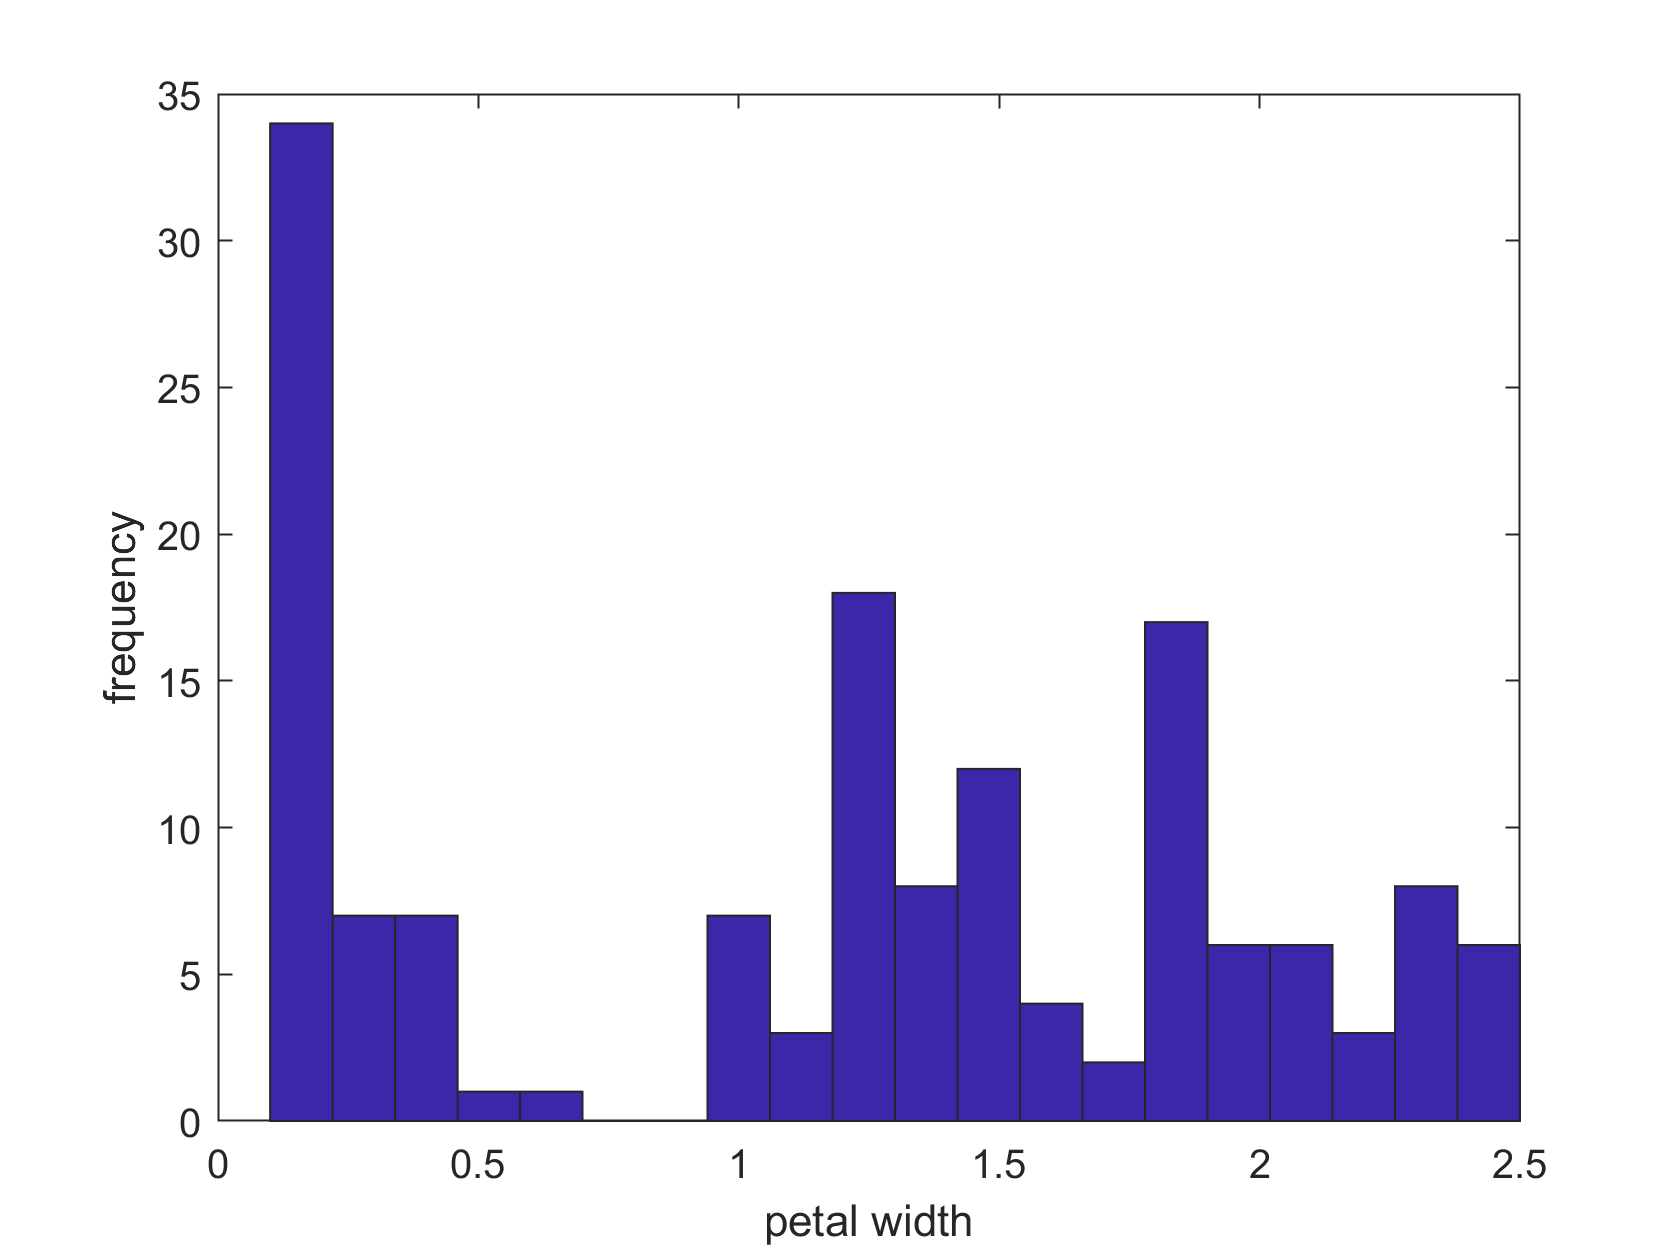

hist(iris, no_bins)
xlabel("petal width")
ylabel("frequency")

*Read the matlab documentation for the ksdensity function. Produce a kernel estimator of the iris data: *

* [f,x,h]=ksdensity(iris); *

* plot(x,f)*

[f,x_i,h] = ksdensity(iris)

f =     0.0015    0.0022    0.0032    0.0046    0.0064    0.0089    0.0121    0.0163    0.0216    0.0282    0.0363    0.0462    0.0578    0.0714    0.0870    0.1046    0.1239    0.1448    0.1669    0.1898    0.2129    0.2357    0.2574    0.2775    0.2954    0.3105    0.3224    0.3310    0.3361    0.3379    0.3366    0.3328    0.3270    0.3200    0.3124    0.3051    0.2987    0.2939    0.2912    0.2909    0.2932    0.2982    0.3056    0.3153    0.3268    0.3397    0.3533    0.3671    0.3807    0.3934


x_i =    -1.1106   -1.0619   -1.0132   -0.9645   -0.9158   -0.8671   -0.8184   -0.7697   -0.7210   -0.6723   -0.6236   -0.5749   -0.5262   -0.4775   -0.4288   -0.3801   -0.3314   -0.2827   -0.2340   -0.1853   -0.1366   -0.0879   -0.0392    0.0095    0.0582    0.1069    0.1556    0.2043    0.2530    0.3017    0.3504    0.3991    0.4478    0.4965    0.5452    0.5939    0.6426    0.6913    0.7400    0.7887    0.8374    0.8861    0.9348    0.9835    1.0322    1.0809    1.1296    1.1783    1.2270    1.2757


h = 0.4035

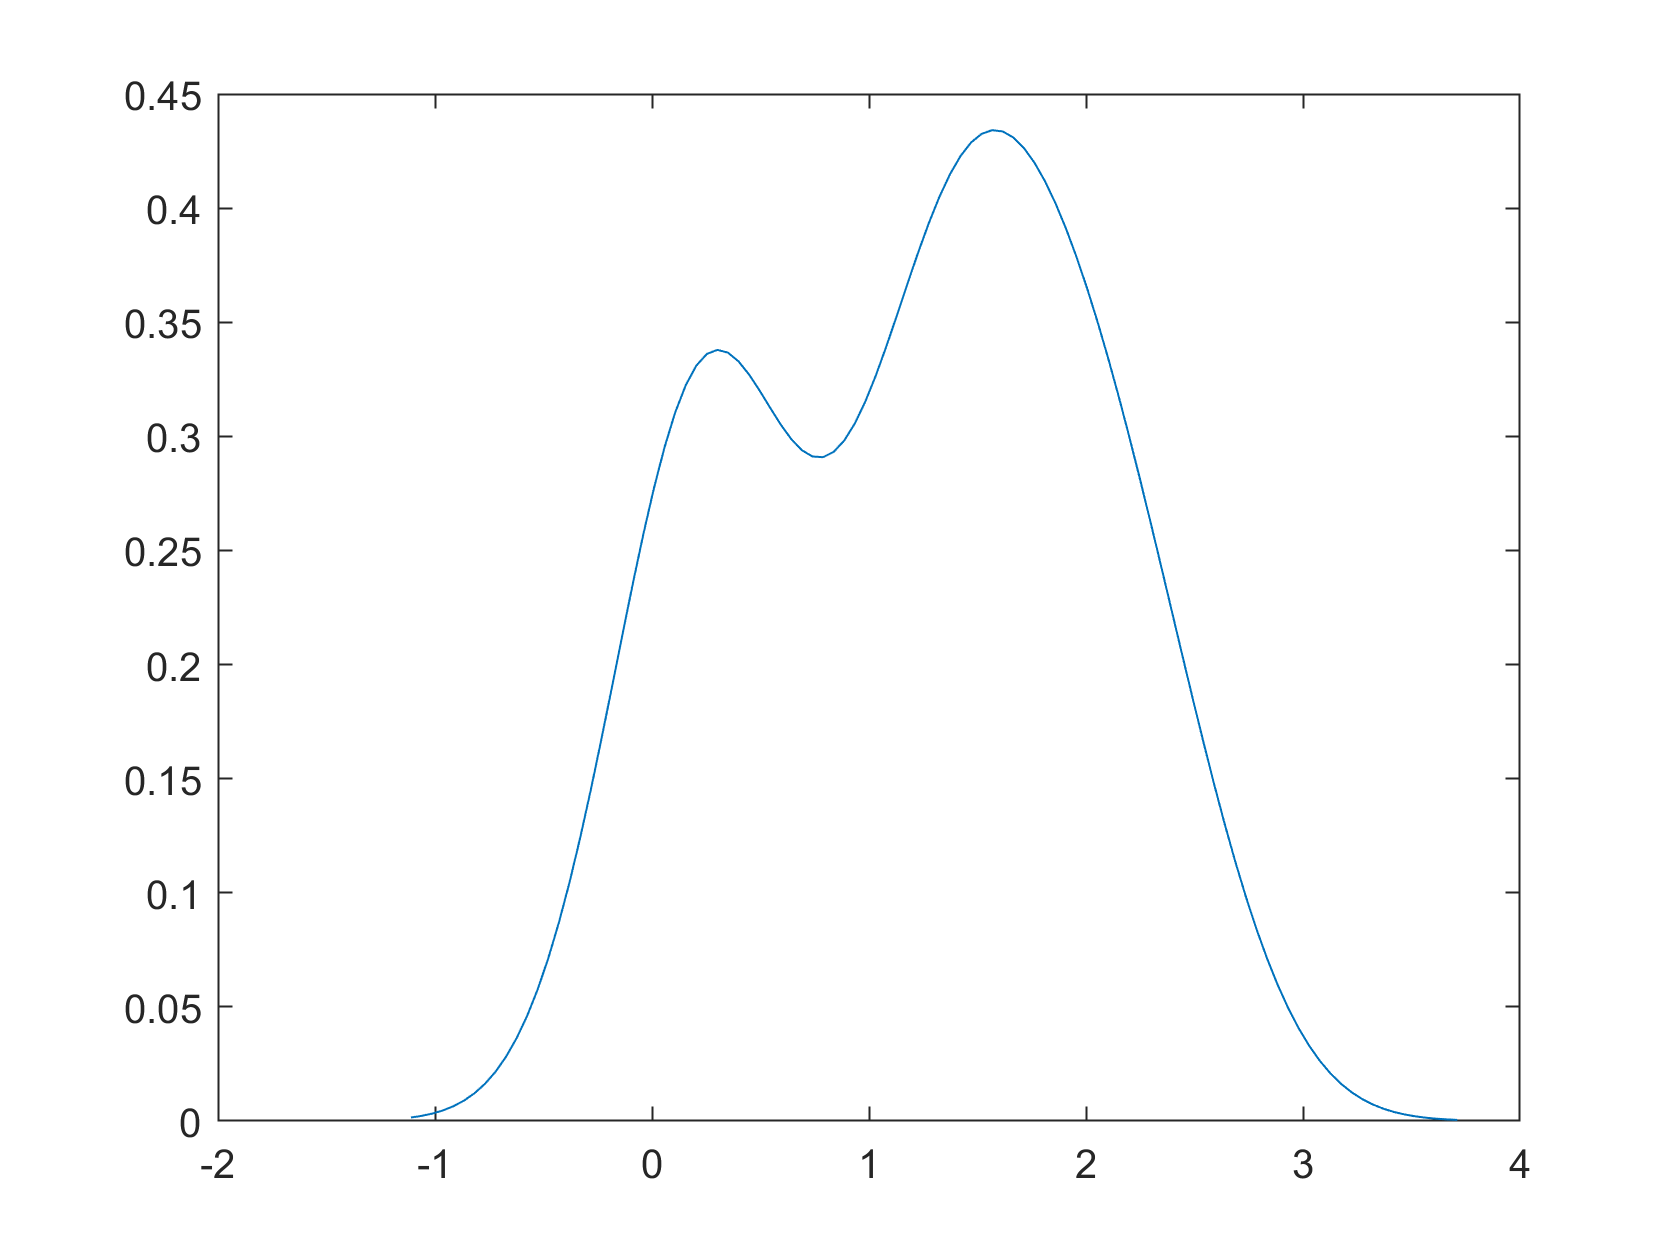

plot(x_i,f)

*What is happening here is that matlab is using a Gaussian kernel, with width ‘h’ parameter chosen automatically (don’t worry too much about how). What is returned are the density values (f) at 100 equally spaced points (x) in the range of the iris data. Also, the value of u gives the value of the width parameter. *

**Q4**: Explore the effect of the width parameter in the estimator by producing a plot to compare (on the same axes): a number of estimators visually: 

The default estimator (note the h value) 

One estimator with larger than the default width 

Two estimators with smaller than the default width.

% h was by default 0.4035
figure
hold on
[f0,x0,h0] = ksdensity(iris, 'Bandwidth', 0.4035)

f0 =     0.0015    0.0022    0.0032    0.0046    0.0064    0.0089    0.0121    0.0163    0.0216    0.0282    0.0363    0.0462    0.0578    0.0715    0.0870    0.1046    0.1239    0.1448    0.1669    0.1898    0.2129    0.2357    0.2574    0.2775    0.2954    0.3105    0.3225    0.3310    0.3361    0.3379    0.3367    0.3328    0.3270    0.3200    0.3124    0.3050    0.2987    0.2939    0.2911    0.2909    0.2932    0.2982    0.3056    0.3153    0.3268    0.3397    0.3533    0.3671    0.3807    0.3934


x0 =    -1.1105   -1.0618   -1.0131   -0.9644   -0.9157   -0.8670   -0.8183   -0.7696   -0.7209   -0.6722   -0.6235   -0.5748   -0.5261   -0.4774   -0.4287   -0.3800   -0.3313   -0.2827   -0.2340   -0.1853   -0.1366   -0.0879   -0.0392    0.0095    0.0582    0.1069    0.1556    0.2043    0.2530    0.3017    0.3504    0.3991    0.4478    0.4965    0.5452    0.5939    0.6426    0.6913    0.7400    0.7887    0.8374    0.8861    0.9348    0.9835    1.0322    1.0809    1.1296    1.1783    1.2270    1.2757


h0 = 0.4035

plot(x0,f0, 'DisplayName', "width = 0.4035")

[f1, x1, h1] = ksdensity(iris, 'Bandwidth', 1)

f1 =     0.0010    0.0013    0.0017    0.0022    0.0028    0.0035    0.0044    0.0055    0.0069    0.0085    0.0104    0.0126    0.0152    0.0182    0.0217    0.0256    0.0301    0.0352    0.0408    0.0471    0.0540    0.0615    0.0696    0.0784    0.0877    0.0976    0.1080    0.1189    0.1301    0.1417    0.1535    0.1655    0.1775    0.1894    0.2013    0.2129    0.2243    0.2352    0.2456    0.2555    0.2647    0.2732    0.2809    0.2877    0.2936    0.2985    0.3023    0.3051    0.3067    0.3071


x1 =    -2.9000   -2.8152   -2.7303   -2.6455   -2.5606   -2.4758   -2.3909   -2.3061   -2.2212   -2.1364   -2.0515   -1.9667   -1.8818   -1.7970   -1.7121   -1.6273   -1.5424   -1.4576   -1.3727   -1.2879   -1.2030   -1.1182   -1.0333   -0.9485   -0.8636   -0.7788   -0.6939   -0.6091   -0.5242   -0.4394   -0.3545   -0.2697   -0.1848   -0.1000   -0.0152    0.0697    0.1545    0.2394    0.3242    0.4091    0.4939    0.5788    0.6636    0.7485    0.8333    0.9182    1.0030    1.0879    1.1727    1.2576


h1 = 1

plot(x1,f1, 'DisplayName', "width = 1")

[f2, x2, h2] = ksdensity(iris, 'Bandwidth', 0.1)

f2 =     0.0020    0.0050    0.0114    0.0242    0.0477    0.0874    0.1495    0.2390    0.3574    0.5000    0.6539    0.7990    0.9123    0.9746    0.9770    0.9240    0.8313    0.7187    0.6038    0.4974    0.4037    0.3226    0.2531    0.1944    0.1465    0.1086    0.0797    0.0580    0.0418    0.0299    0.0220    0.0185    0.0207    0.0301    0.0484    0.0764    0.1132    0.1558    0.1990    0.2374    0.2674    0.2891    0.3061    0.3248    0.3512    0.3890    0.4379    0.4932    0.5477    0.5942


x2 =    -0.2000   -0.1697   -0.1394   -0.1091   -0.0788   -0.0485   -0.0182    0.0121    0.0424    0.0727    0.1030    0.1333    0.1636    0.1939    0.2242    0.2545    0.2848    0.3152    0.3455    0.3758    0.4061    0.4364    0.4667    0.4970    0.5273    0.5576    0.5879    0.6182    0.6485    0.6788    0.7091    0.7394    0.7697    0.8000    0.8303    0.8606    0.8909    0.9212    0.9515    0.9818    1.0121    1.0424    1.0727    1.1030    1.1333    1.1636    1.1939    1.2242    1.2545    1.2848


h2 = 0.1000

plot(x2,f2, 'DisplayName', "width = 0.1")

[f3, x3, h3] = ksdensity(iris, 'Bandwidth', 0.01)

f3 =     0.0177    1.3975    0.2294    0.0001    0.0688    6.3095    1.2038    0.0005    0.0143    1.5205    0.3372    0.0002    0.0118    1.4603    0.3765    0.0002    0.0014    0.1996    0.0598    0.0000    0.0011    0.1903    0.0663    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0035    1.0608    0.6752    0.0009    0.0012    0.4256    0.3149    0.0005    0.0016    0.6615    0.5690    0.0010    0.0033    1.5980


x3 =     0.0700    0.0948    0.1197    0.1445    0.1694    0.1942    0.2191    0.2439    0.2688    0.2936    0.3185    0.3433    0.3682    0.3930    0.4179    0.4427    0.4676    0.4924    0.5173    0.5421    0.5670    0.5918    0.6167    0.6415    0.6664    0.6912    0.7161    0.7409    0.7658    0.7906    0.8155    0.8403    0.8652    0.8900    0.9148    0.9397    0.9645    0.9894    1.0142    1.0391    1.0639    1.0888    1.1136    1.1385    1.1633    1.1882    1.2130    1.2379    1.2627    1.2876


h3 = 0.0100

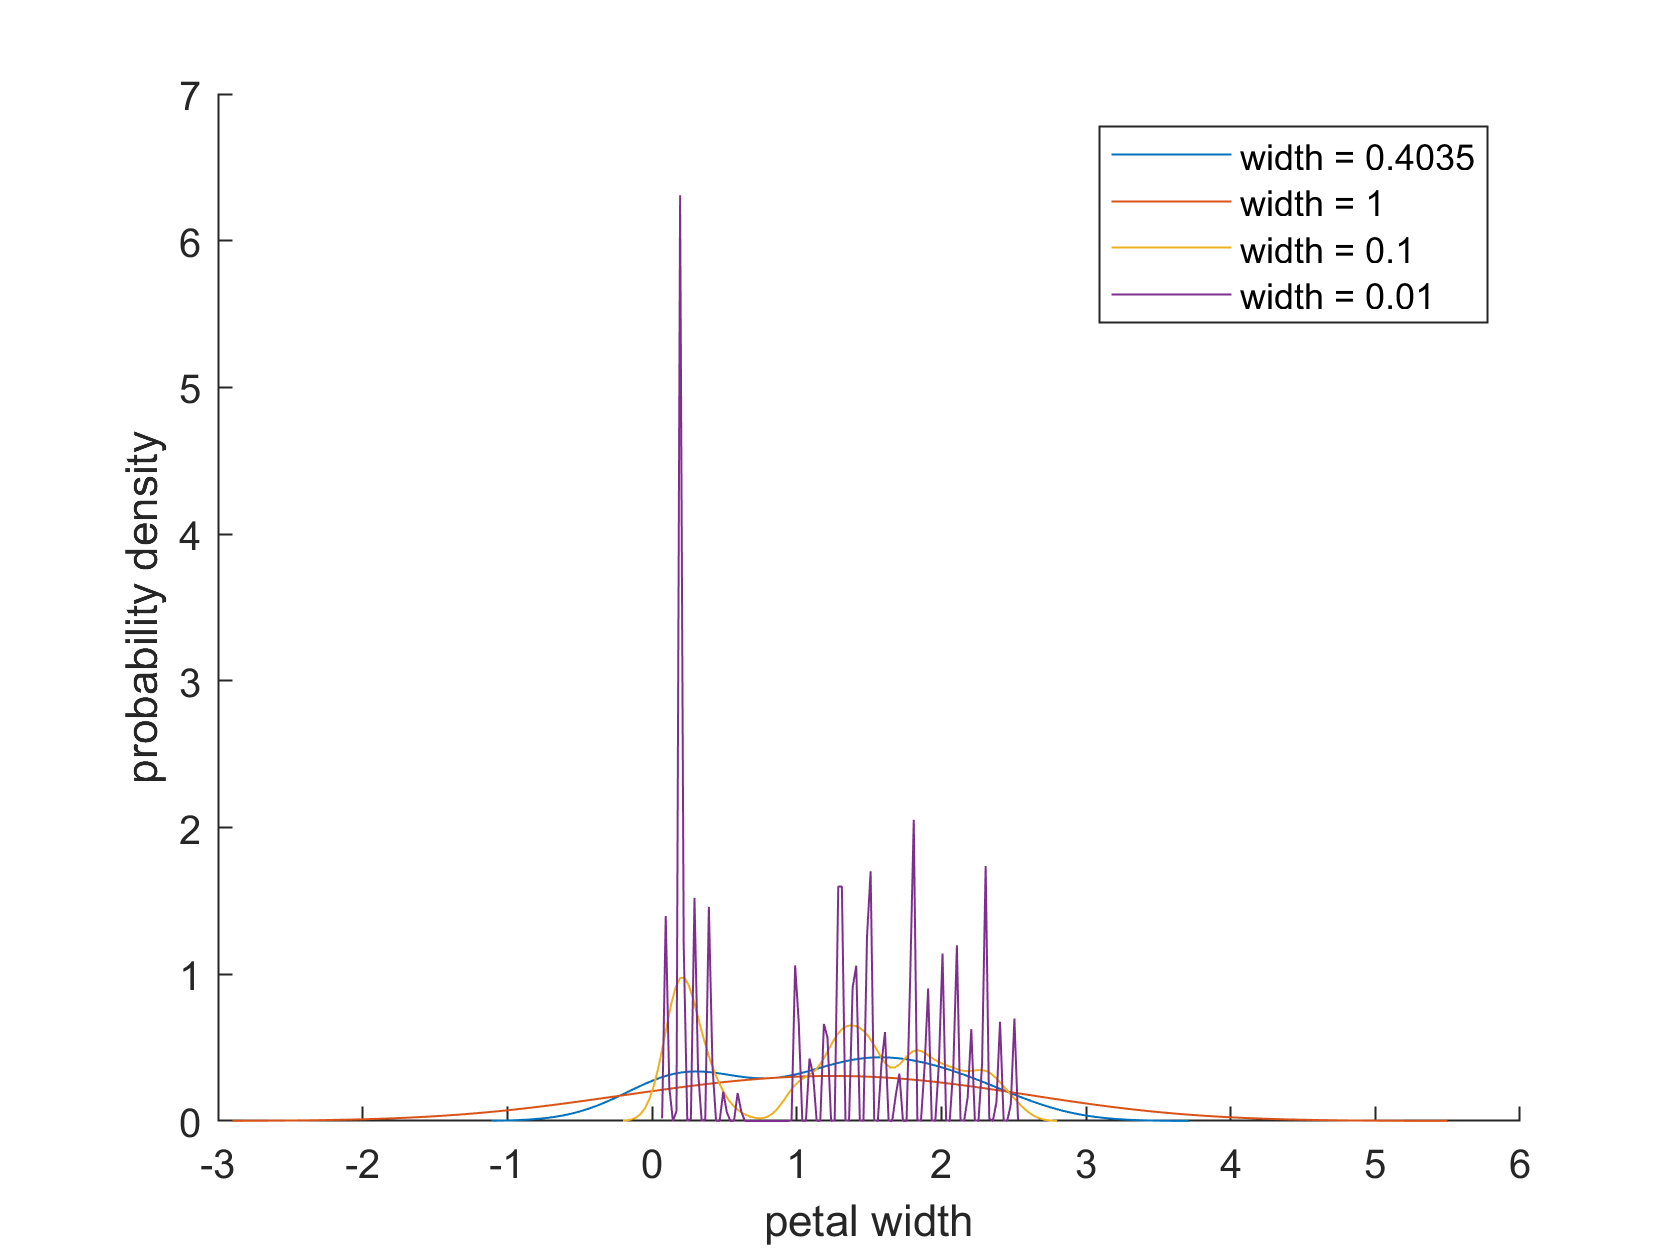

plot(x3,f3, 'DisplayName', "width = 0.01")

xlabel("petal width")
ylabel("probability density")
legend

hold off

*It is often not easy to evaluate the “goodness” of a density estimator quantitatively, since we do not know the true distribution which produced the data. The situation is worse than for supervised learning because we don’t even have a labelled set of data (which in this case would be a set of data points together with the true value of the density at each point). One approach (as mentioned in lectures and the book) is to measure likelihood on a validation set. *

*On the other hand, if we’re just testing algorithms then we can generate our data from a known distribution. If we then build a density estimator from such data, we can compare the estimator with the true distribution that generated the data. A commonly used measure to compare probability distributions is the Kullback-Leibler (KL) divergence: *

*where p(x) is the true distribution and q(x) is the model distribution (see e.g. wikipedia for more info). *

*→ Generate a dataset from a mixture of two Gaussians: *

* x = [randn(30,1); 5+randn(30,1)];*

% add a random seed
rng('default')
s = rng

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]



x = [randn(30,1); 5+randn(30,1)]; % therefore means are 0 and 5, std's are 1 and 1

*Build a histogram model (H1) for this data with 20 bins.*

% just show a histogram to start with, we will create the model further down
no_bins = 20

no_bins = 20

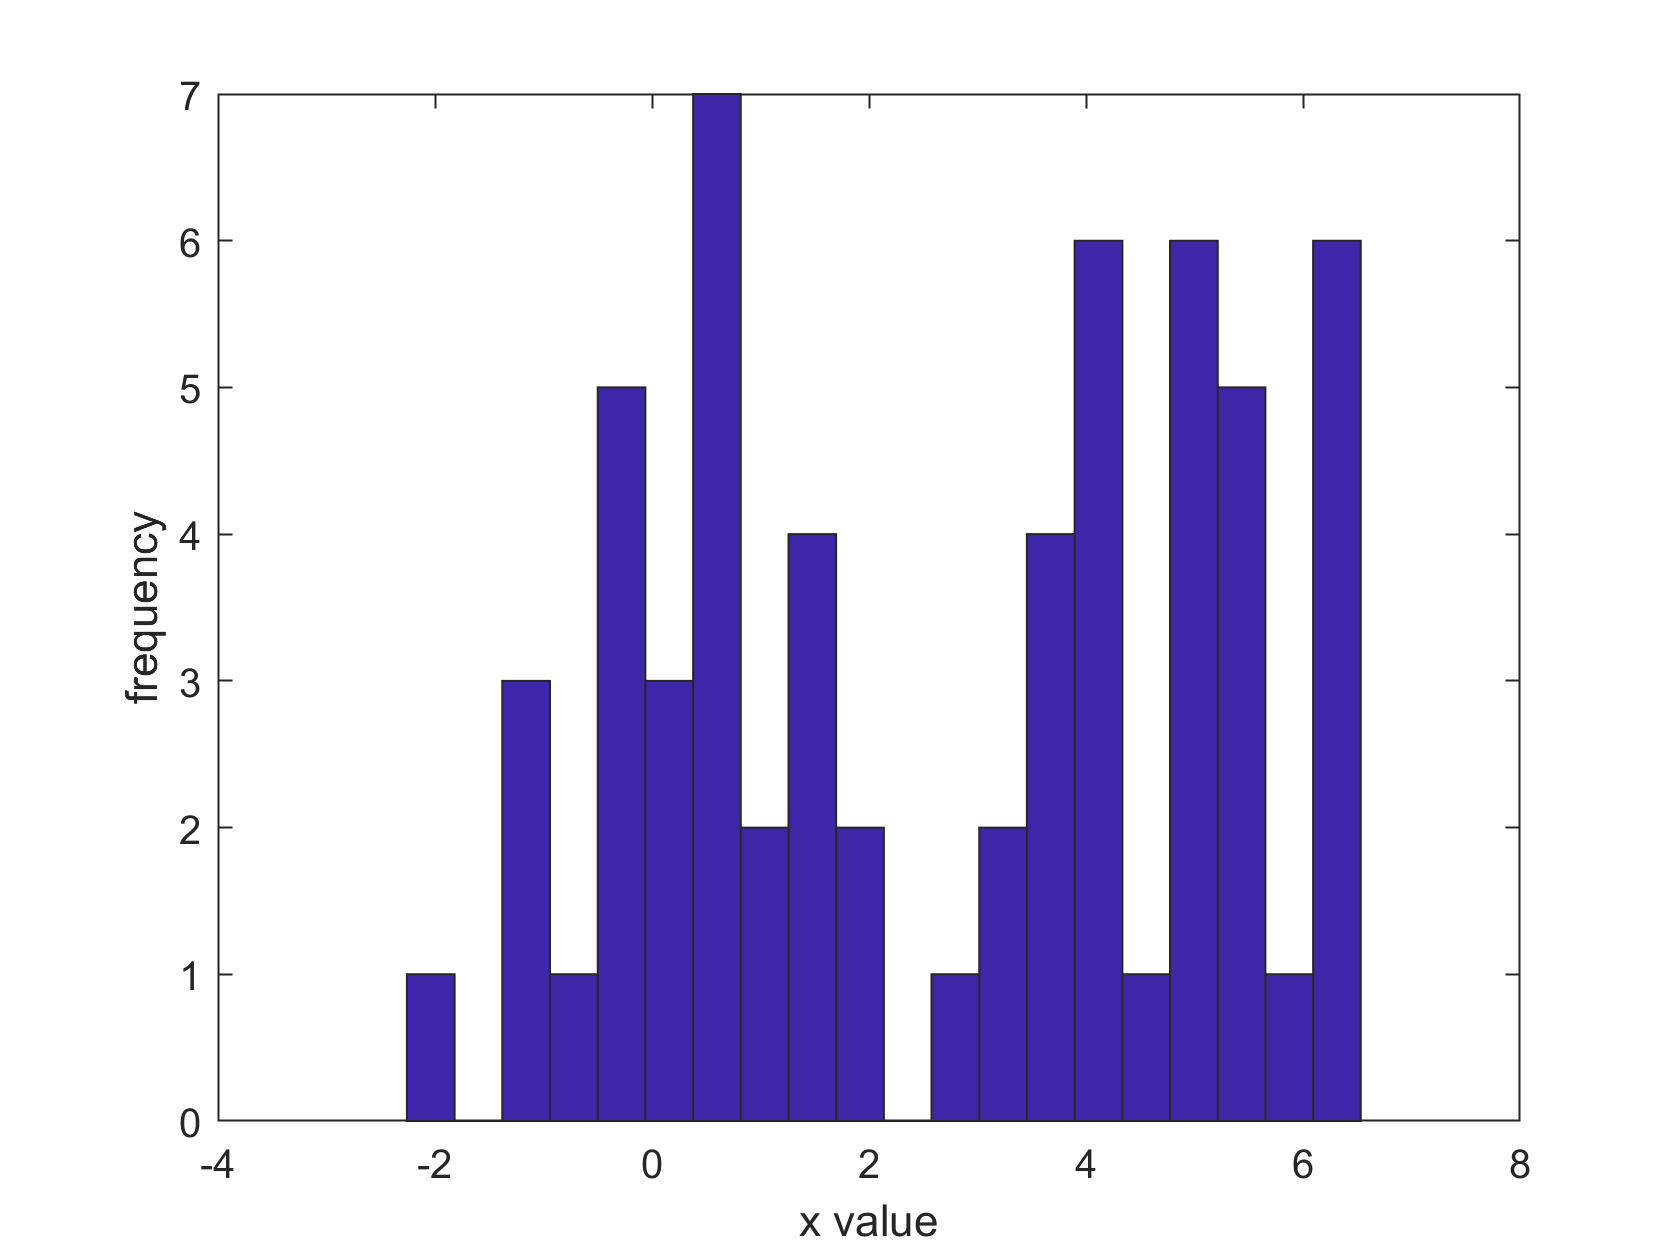

hist(x, no_bins)
xlabel("x value")
ylabel("frequency")

*Build two kernel density estimators (K1 and K2) for the data: one with the default kernel width value and one with a width value equal to half the default value.*

figure
hold on
% default h value
[fx1,xx1,hx1] = ksdensity(x)

fx1 =     0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0008    0.0010    0.0014    0.0018    0.0024    0.0031    0.0039    0.0050    0.0062    0.0077    0.0095    0.0115    0.0139    0.0167    0.0198    0.0233    0.0271    0.0314    0.0360    0.0410    0.0462    0.0518    0.0575    0.0634    0.0693    0.0752    0.0809    0.0863    0.0914    0.0959    0.1000    0.1034    0.1061    0.1082    0.1095    0.1103    0.1104    0.1101    0.1094    0.1085    0.1075    0.1066    0.1058


xx1 =    -6.8010   -6.6204   -6.4399   -6.2593   -6.0788   -5.8982   -5.7176   -5.5371   -5.3565   -5.1759   -4.9954   -4.8148   -4.6342   -4.4537   -4.2731   -4.0926   -3.9120   -3.7314   -3.5509   -3.3703   -3.1897   -3.0092   -2.8286   -2.6480   -2.4675   -2.2869   -2.1064   -1.9258   -1.7452   -1.5647   -1.3841   -1.2035   -1.0230   -0.8424   -0.6618   -0.4813   -0.3007   -0.1202    0.0604    0.2410    0.4215    0.6021    0.7827    0.9632    1.1438    1.3244    1.5049    1.6855    1.8660    2.0466


hx1 = 1.5141

plot(xx1,fx1, 'DisplayName', strcat("K1: width = ", num2str(hx1)))

% half default h value
[fx2, xx2, hx2] = ksdensity(x, 'Bandwidth', hx1/2)

fx2 =     0.0001    0.0002    0.0003    0.0004    0.0007    0.0010    0.0015    0.0022    0.0030    0.0041    0.0054    0.0070    0.0090    0.0112    0.0138    0.0167    0.0200    0.0237    0.0277    0.0320    0.0367    0.0418    0.0471    0.0528    0.0588    0.0652    0.0721    0.0793    0.0870    0.0952    0.1036    0.1121    0.1205    0.1285    0.1357    0.1417    0.1463    0.1491    0.1500    0.1489    0.1458    0.1409    0.1345    0.1269    0.1185    0.1098    0.1010    0.0927    0.0851    0.0787


xx2 =    -4.5299   -4.3952   -4.2606   -4.1259   -3.9912   -3.8565   -3.7218   -3.5871   -3.4525   -3.3178   -3.1831   -3.0484   -2.9137   -2.7790   -2.6444   -2.5097   -2.3750   -2.2403   -2.1056   -1.9709   -1.8363   -1.7016   -1.5669   -1.4322   -1.2975   -1.1628   -1.0282   -0.8935   -0.7588   -0.6241   -0.4894   -0.3547   -0.2201   -0.0854    0.0493    0.1840    0.3187    0.4534    0.5880    0.7227    0.8574    0.9921    1.1268    1.2615    1.3961    1.5308    1.6655    1.8002    1.9349    2.0696


hx2 = 0.7570

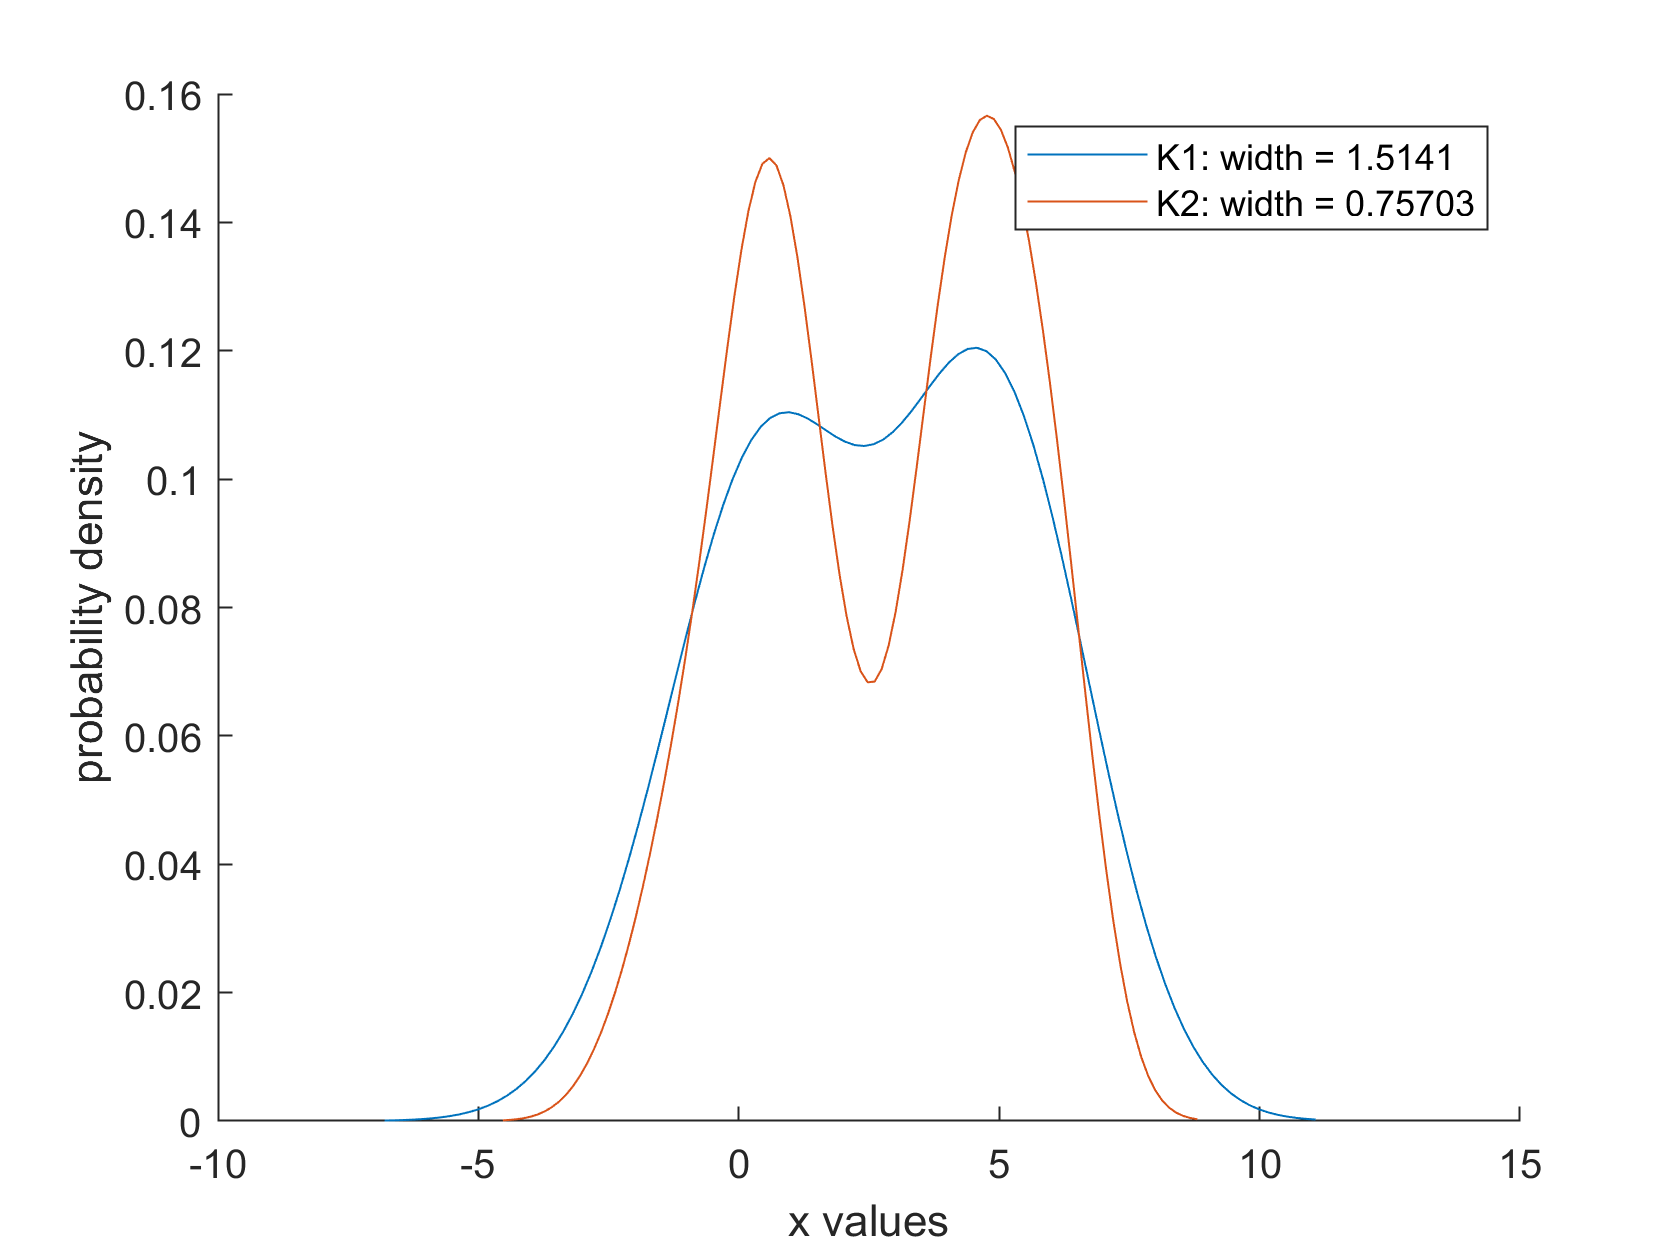

plot(xx2,fx2, 'DisplayName', strcat("K2: width = ", num2str(hx1/2)))

xlabel("x values")
ylabel("probability density")
legend

hold off

***Q5****: Calculate the KL divergence (based on 100 equally spaced “test” points that cover the range of the data in x), between: *

*M and H1 - see Alpaydin eqn 8.3*

*M and K1 *

*M and K2 *

*where M is the distribution given by the mixture of 2 Gaussians. In addition to the 3 KL divergence values, provide the code used to calculate them. Include and discuss any assumptions or “work-arounds” you used.*

x = [randn(30,1); 5+randn(30,1)]; -> therefore means are 0 and 5, std's are 1 and 1

% first get 100 equally spaced points across the range of x
test_points = linspace(min(x), max(x), 100);

% we know these values from the randn function
M_1_m = 0;
M_2_m = 5;

M_1_std = 1;
M_2_std = 1;

M_1 = normpdf(test_points, M_1_m, M_1_std);
M_2 = normpdf(test_points, M_2_m, M_2_std);

M = M_1*0.5 + M_2*0.5;

[K1,xx1,hx1] = ksdensity(x); % by default evaluates over 100 test points equally spaced between min(x) and max(x)
[K2,xx2,hx2] = ksdensity(x, 'Bandwidth', hx1/2);

KL_div_K1 = sum(M.*log(M./K1))

KL_div_K1 = 19.3506

KL_div_K2 = sum(M.*log(M./K2))

KL_div_K2 = 11.6468


% hist values
no_bins = 20;
width = (max(x) - min(x))/no_bins;
H1 = hist(x,no_bins)/ (length(x) * width) % you may need to do something to this equation to get a non 'inf' KL divergence.

H1 =     0.0379         0    0.1137    0.0379    0.1896    0.1137    0.2654    0.0758    0.1517    0.0758         0    0.0379    0.0758    0.1517    0.2275    0.0379    0.2275    0.1896    0.0379    0.2275


H1 = repelem(H1, 5) % boosts quantity to 100 points

H1 =     0.0379    0.0379    0.0379    0.0379    0.0379         0         0         0         0         0    0.1137    0.1137    0.1137    0.1137    0.1137    0.0379    0.0379    0.0379    0.0379    0.0379    0.1896    0.1896    0.1896    0.1896    0.1896    0.1137    0.1137    0.1137    0.1137    0.1137    0.2654    0.2654    0.2654    0.2654    0.2654    0.0758    0.0758    0.0758    0.0758    0.0758    0.1517    0.1517    0.1517    0.1517    0.1517    0.0758    0.0758    0.0758    0.0758    0.0758



KL_div_H1 = sum(M.*log(M./H1)) % if this is 'inf' you will need to think of a "work-around"

KL_div_H1 = Inf

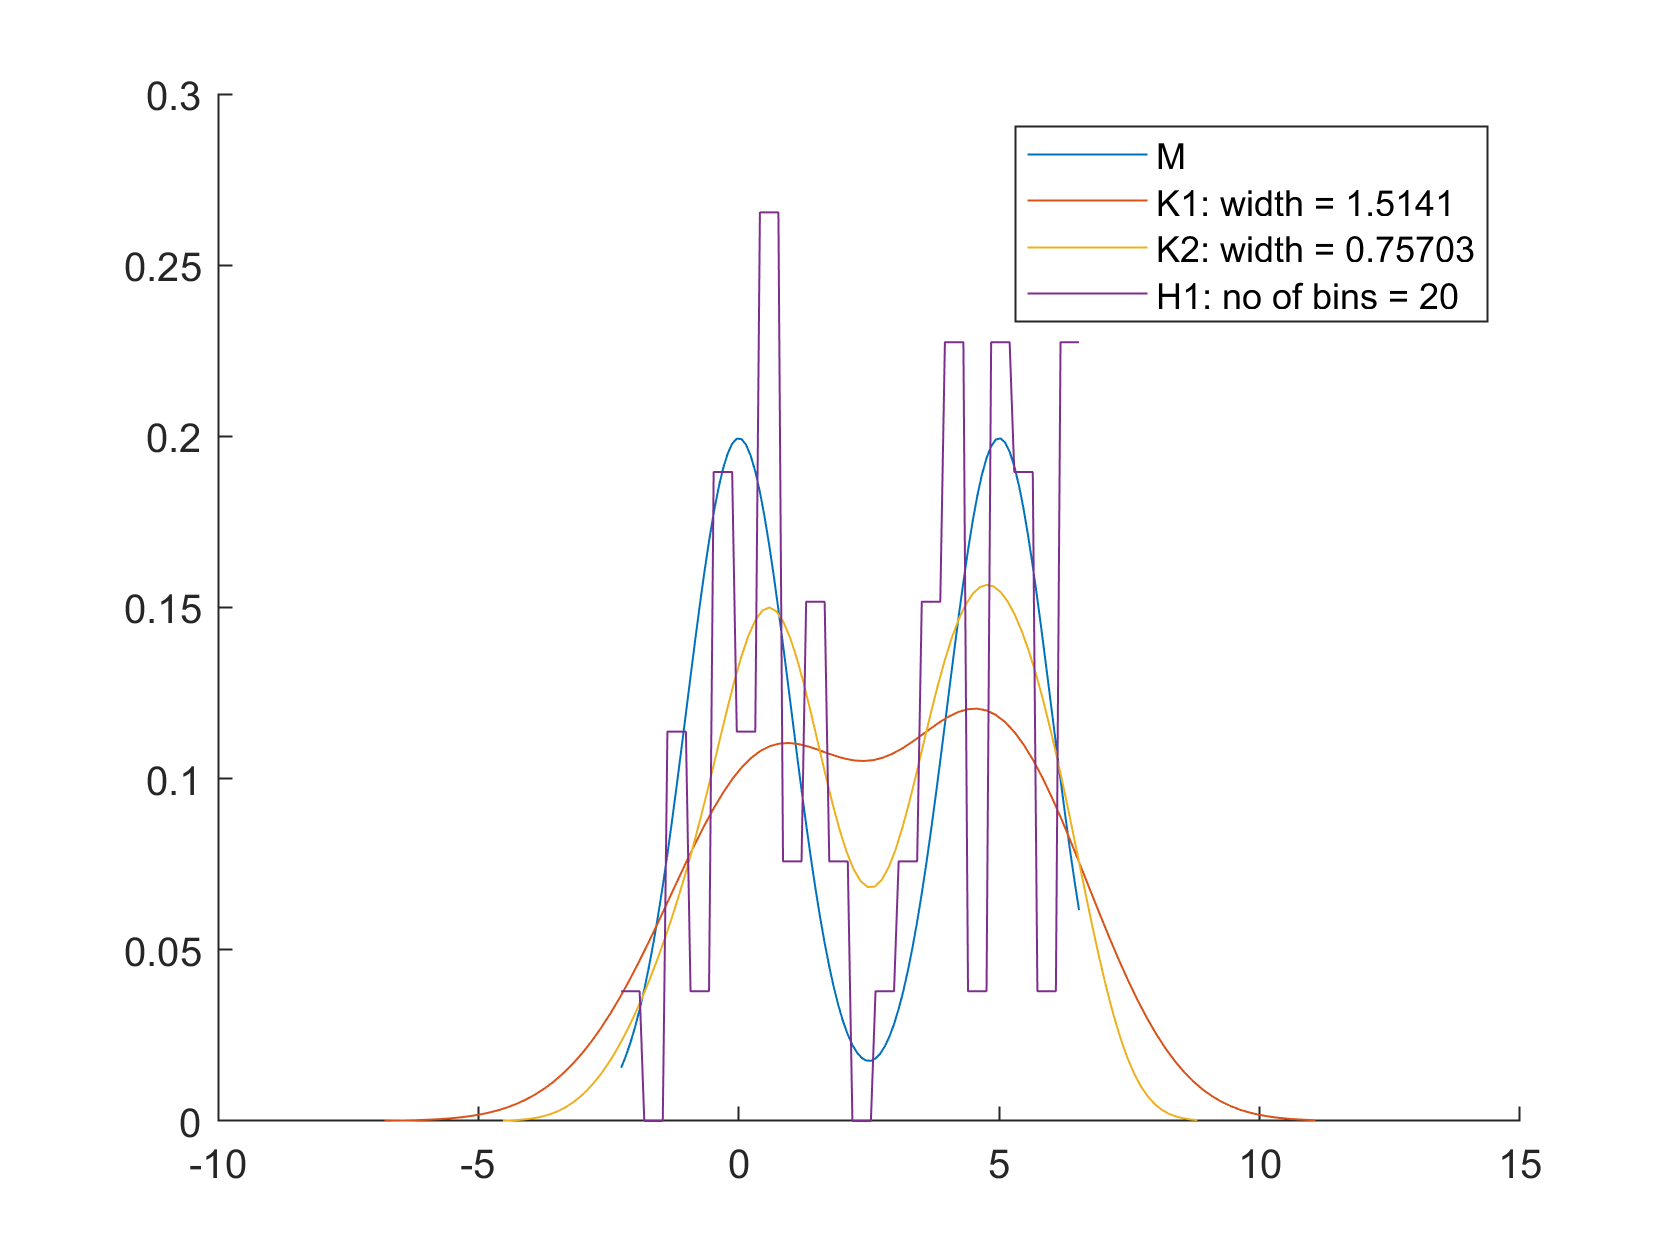


% visually see how the different distributions compared to M
figure
hold on
plot(test_points,M, 'DisplayName', "M")
plot(xx1,K1, 'DisplayName', strcat("K1: width = ", num2str(hx1)))
plot(xx2,K2, 'DisplayName', strcat("K2: width = ", num2str(hx1/2)))
plot(test_points, H1, 'DisplayName', strcat("H1: no of bins = ", num2str(no_bins)))

legend;
hold off

*Some hints: *

*Recall mixture models from the clustering lecture: the distribution M above is a simple mixture with two components, each with a prior/mixing coefficient with value 0.5. *

*The matlab normpdf() function evaluates the density of a Gaussian at a given point. *

*The test points required are calculated via the ksdensity function.*